% Set which environment displays
env = 2

env = 2


% Define environment criteria
if env == 1
disp('Environment 1 - 1 can, no wall, no roof')
floor = collisionBox(1, 1, 0.01);
tabletop1 = collisionBox(0.4,1,0.02);
tabletop1.Pose = trvec2tform([0.3,0,0.6]);
tabletop2 = collisionBox(0.6,0.2,0.02);
tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
can = collisionCylinder(0.03,0.16);
can.Pose = trvec2tform([0.3,0.0,0.7]);
worldCollisionArray = {floor tabletop1 tabletop2 can};

elseif env == 2
disp('Environment 2 - 1 can, side walls, no roof')
floor = collisionBox(1, 1, 0.01);
tabletop1 = collisionBox(0.4,1,0.02);
tabletop1.Pose = trvec2tform([0.3,0,0.6]);
tabletop2 = collisionBox(0.6,0.2,0.02);
tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
can = collisionCylinder(0.03,0.16);
can.Pose = trvec2tform([0.3,0.0,0.7]);
sidewall1 = collisionBox(0.4,0.03,0.3);
sidewall1.Pose = trvec2tform([0.3,-0.25,0.77]);
sidewall2 = collisionBox(0.4,0.03,0.3);
sidewall2.Pose = trvec2tform([0.3,0.25,0.77]);
worldCollisionArray = {floor tabletop1 tabletop2 can sidewall1 sidewall2};

elseif env == 3
disp('Environment 3 - 1 can, side walls, roof')
floor = collisionBox(1, 1, 0.01);
tabletop1 = collisionBox(0.4,1,0.02);
tabletop1.Pose = trvec2tform([0.3,0,0.6]);
tabletop2 = collisionBox(0.6,0.2,0.02);
tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
can = collisionCylinder(0.03,0.16);
can.Pose = trvec2tform([0.3,0.0,0.7]);
worldCollisionArray = {floor tabletop1 tabletop2 can};

elseif env == 4
disp('Environment 4 - 3 cans, no walls, no roof')
floor = collisionBox(1, 1, 0.01);
tabletop1 = collisionBox(0.4,1,0.02);
tabletop1.Pose = trvec2tform([0.3,0,0.6]);
tabletop2 = collisionBox(0.6,0.2,0.02);
tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
can = collisionCylinder(0.03,0.16);
can.Pose = trvec2tform([0.3,0.0,0.7]);
can2 = collisionCylinder(0.03,0.16);
can2.Pose = trvec2tform([0.2,-0.15,0.7]);
can3 = collisionCylinder(0.03,0.16);
can3.Pose = trvec2tform([0.4,0.15,0.7]);
worldCollisionArray = {floor tabletop1 tabletop2 can can2 can3};

elseif env == 5
disp('Environment 5 - 3 cans, side walls, no roof')
floor = collisionBox(1, 1, 0.01);
tabletop1 = collisionBox(0.4,1,0.02);
tabletop1.Pose = trvec2tform([0.3,0,0.6]);
tabletop2 = collisionBox(0.6,0.2,0.02);
tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
can = collisionCylinder(0.03,0.16);
can.Pose = trvec2tform([0.3,0.0,0.7]);
can2 = collisionCylinder(0.03,0.16);
can2.Pose = trvec2tform([0.2,-0.15,0.7]);
can3 = collisionCylinder(0.03,0.16);
can3.Pose = trvec2tform([0.4,0.15,0.7]);
worldCollisionArray = {floor tabletop1 tabletop2 can can2 can3};

elseif env == 6
disp('Environment 6 - 3 cans, side walls, roof')
floor = collisionBox(1, 1, 0.01);
tabletop1 = collisionBox(0.4,1,0.02);
tabletop1.Pose = trvec2tform([0.3,0,0.6]);
tabletop2 = collisionBox(0.6,0.2,0.02);
tabletop2.Pose = trvec2tform([-0.2,0.4,0.5]);
can = collisionCylinder(0.03,0.16);
can.Pose = trvec2tform([0.3,0.0,0.7]);
can2 = collisionCylinder(0.03,0.16);
can2.Pose = trvec2tform([0.2,-0.15,0.7]);
can3 = collisionCylinder(0.03,0.16);
can3.Pose = trvec2tform([0.2,0.15,0.7]);
worldCollisionArray = {floor tabletop1 tabletop2 can can2 can3};
end

Environment 2 - 1 can, side walls, no roof


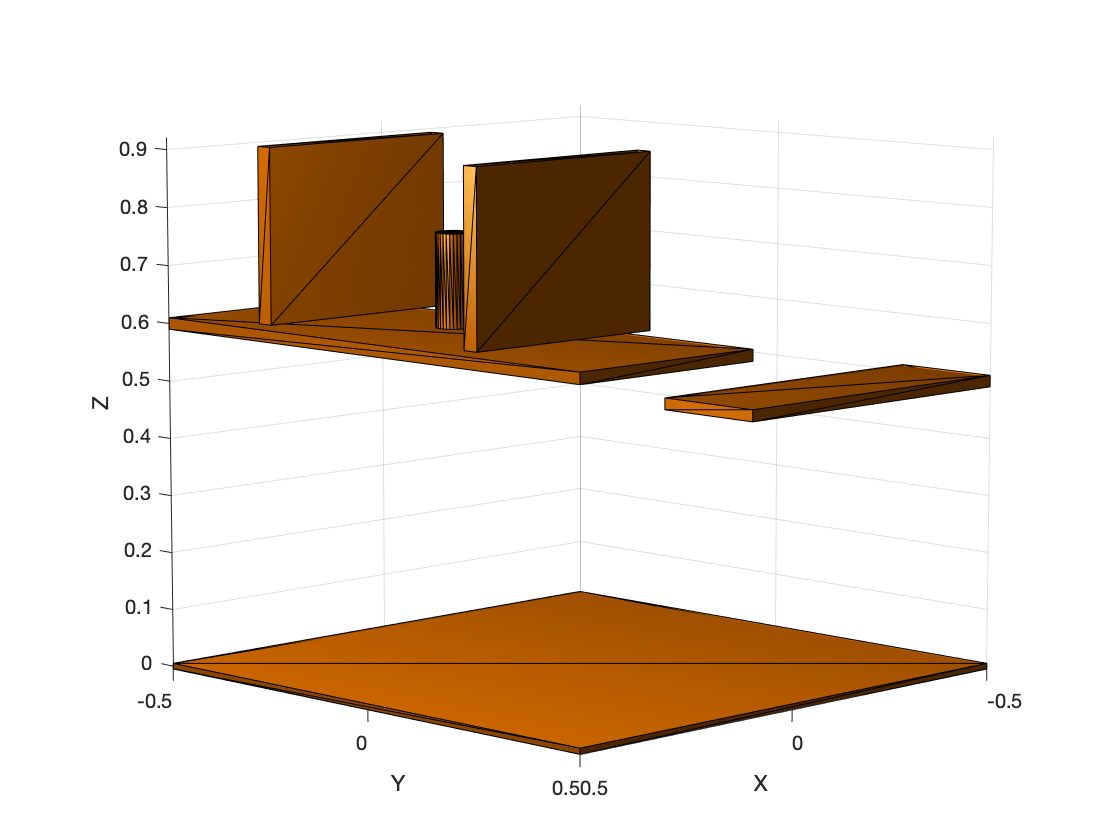


% Generate visual
exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);